# Testing the Advanced 2-Beam Purturbation Method

## Clear variables between Runs:

clear % clear variables and everything
clc % clear command window

## Set up Save Path

saveDir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Saved_Results';
%if ~exist(saveDir, 'dir')
%    mkdir(saveDir);
%end

## Select Parameters:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
params.freq = 3e9;
params.lambda = 3e8 / params.freq; 
lambda = params.lambda; 
%params.N = 9;
%N = params.N; %Number of drones

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
phi_mesh = linspace(0, 2*pi, 1000+1);
phi_mesh(end) = [];   % remove 2π duplicate

## Generate Initial Configuration (To serve as a starting point for our optimization)

% Initialize nieve 9-element "double cross" coordinates
%x = [0 0 0 0.5*lambda -0.5*lambda 0.5*lambda -0.5*lambda lambda -lambda]';
%y = [0 0.5*lambda -0.5*lambda 0 0 0.5*lambda -0.5*lambda lambda -lambda]';
    
% Initialize Daniil's "good" version of the 9-element "double cross" coordinates
%z = zeros(1,N);
%d1 = 0.422 * lambda;
%d2 = 0.554 * lambda;
%[x,y] = d1d2Convert(d1,d2,N);

% Initialize Eric's 'better' version for 120 degrees
%d1 = 0.049553426571036;
%d2 = 0.049015017974167;

%d1 = 0.049553426571036;	
%d2 = 0.049015017974167;
%d1 = 0.029394;
%d2 = 0.0341;
%[x,y] = d1d2Convert(d1,d2,N);

% These should be the "true correct 9 element ones" from the meeting with everybody
x = [0	-0.042211347450806	0.042211347450806	0	0	0.039173549691350	-0.039173549691350	-0.039173549691350	0.039173549691350];
y = [0	0	0	0.042211347450806	-0.042211347450806	0.039173549691350	0.039173549691350	-0.039173549691350	-0.039173549691350];

% Initialize test version without center emitter
%x(1) = [];
%y(1) = [];

% Initialize test version with two elements
%x = [0 lambda/2];
%y = [0 0];

% Eric's optimal "5 element setup"
%x = [0, 0.019598444542977, 0, -0.019598444542977, 0];
%y = [0, 0, 0.019598444542977, 0, -0.019598444542977];

## Set-up and Run the Advanced 2-Beam version of the Algorithm

%% Start Function
Max_iter = 20; %The algithm goes to step maxiter
eps_dB = -20;
phi_0_1 = deg2rad(150);
phi_0_2 = deg2rad(275);
phi_0_set = [phi_0_1 phi_0_2];
cone_rad = [];
cone_rad = deg2rad(50);
results_2b = perturb_method_2_beam_v3(x, y, phi_0_1, phi_0_2,...
    'Max_iter', Max_iter, ...
    'eps_dB', eps_dB, ...
    'show_plot_init', false, ...
    'cone_rad', cone_rad)

results_2b = struct with fields:
                               final_epoch: 5
                           final_iteration: 6
                                total_time: 0.0197
                                  cone_rad: 0.8727
                            final_function: [0.0884 0.0885 0.0884 0.0883 0.0881 0.0878 0.0874 0.0870 0.0864 0.0858 0.0852 0.0844 0.0836 0.0827 0.0818 0.0808 0.0797 0.0786 0.0775 0.0762 0.0750 0.0736 0.0723 0.0709 0.0694 0.0679 0.0664 … ] (1×1000 double)
                          initial_function: [3.8702 3.7631 3.6554 3.5473 3.4386 3.3295 3.2200 3.1101 2.9998 2.8892 2.7783 2.6671 2.5557 2.4441 2.3324 2.2205 2.1085 1.9965 1.8844 1.7723 1.6603 1.5483 1.4364 1.3247 1.2132 1.1018 0.9908 … ] (1×1000 double)
                             focus_angle_1: 2.6180
                         focus_angle_1_deg: 150
                             focus_angle_2: 4.7997
                         focus_angle_2_deg: 275
                           Big_Val_final_1: 1.5638
                

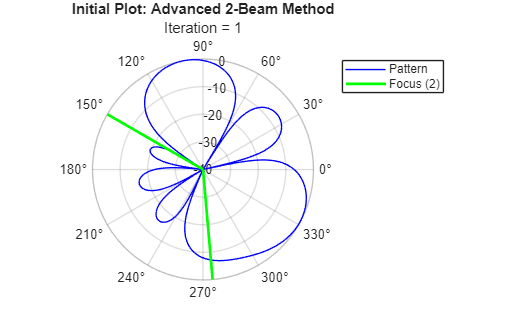


%{
results1 = perturb_method_v15(Max_iter, eps_dB, x, y, ...
    phi_0, ...
    'verbose', false, ...
    'null_phi', null_phi_list, ...
    'show_plots', false, ...
    'show_plot_raw', false, ...
    'show_plot_init', false, ...
    'show_plots_st7', false, ...
    'show_plots_st12', false, ...
    'show_final_plot',  false, ...
    'cone_rad', cone_rad)
%}

bw1 = directivity_met_v2(phi_mesh, results_2b.initial_function, phi_0_1);
bw2 = directivity_met_v2(phi_mesh, results_2b.initial_function, phi_0_2);
phi_mesh = linspace(0, 2*pi, 1000);
lab_1 = "Initial Plot: Advanced 2-Beam Method";
%lab_1 = "Final Plot: PROTOTYPE New Basic 2-Beam";
%lab_1 = "Final Plot: 1-Beam-1-Null-Const Method";
            % View function graph
            plot_pattern_v4(phi_mesh, ...
                results_2b.initial_function, ...
                'label',lab_1, ...
                'phi_0', phi_0_set, ...
                'show_plots', true, ...
                'cone_rad', [], ...
                'bw_edges_right', [bw1.right_05 bw2.right_05],...
                'bw_edges_left', [bw1.left_05 bw2.left_05],...
                'iter', 1);

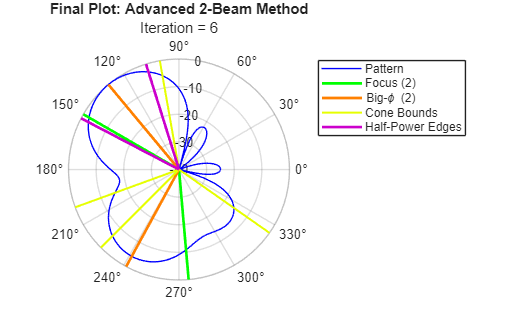

phi_mesh = linspace(0, 2*pi, 1000);

%bw = directivity_met_v2(phi_mesh, resultsPROTO.final_function, phi_0);
bw1 = directivity_met_v2(phi_mesh, results_2b.final_function, phi_0_1);
bw2 = directivity_met_v2(phi_mesh, results_2b.final_function, phi_0_2);

lab_1 = "Final Plot: Advanced 2-Beam Method";
%lab_1 = "Final Plot: PROTOTYPE 1-Beam-0-Null";
%lab_1 = "Final Plot: 1-Beam-1-Null-Const Method";
            % View function graph
            plot_pattern_v5(phi_mesh, ...
                results_2b.final_function, ...
                'label',lab_1, ...
                'phi_0', phi_0_set, ...
                'phi_s', [], ...
                'Slobe', [], ...
                'iter', results_2b.final_iteration, ...
                'show_plots', true, ...
                'cone_rad', results_2b.cone_rad, ...
                'bw_edges_right', [bw1.right_05 bw2.right_05],...
                'bw_edges_left', [bw1.left_05 bw2.left_05],...
                'Big_phi', [results_2b.Big_phi_final_1 results_2b.Big_phi_final_2]);



saveFile = fullfile(saveDir, 'advanced_2beam.mat');
save(saveFile, ...
    'results_2b', ...
    'phi_0_1', ...
    'phi_0_2', ...
    'eps_dB', ...
    'Max_iter');


## Plot Max Sidelobe vs. Epoch Number (2-Beam Advanced)

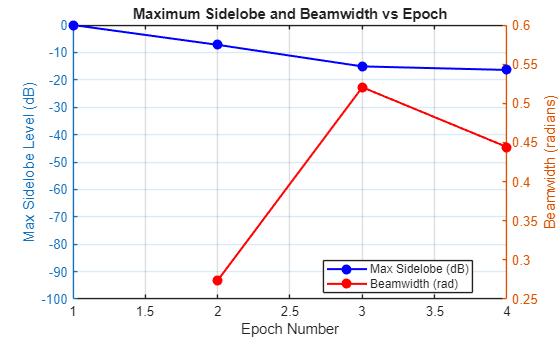

loadFile = fullfile(saveDir, 'advanced_2beam.mat');
load(loadFile);

%% === Plot Maximum Sidelobe, Beamwidth, and Focus Value vs Epoch ===

sl_store = results_2b.max_sidelobe_store;
bw_store_1 = results_2b.directivity_metric_1_beamwidth_store_1;
bw_store_2 = results_2b.directivity_metric_1_beamwidth_store_2;


% Determine valid entries
valid_mask = ~(isnan(sl_store) | isinf(sl_store));
last_valid = find(valid_mask, 1, 'last');

if isempty(last_valid)
    error('No valid sidelobe entries found in results1.max_sidelobe_store');
end

% Trim
sl_valid = sl_store(1:last_valid);
%bw_valid = bw_store(1:last_valid);
bw_valid_1 = bw_store_1(1:last_valid);
bw_valid_2 = bw_store_2(1:last_valid);

epochs = 1:last_valid;

% Skip the first 5 points
Nskip = 0;

sl_valid = sl_valid(Nskip+1:end);
%bw_valid = bw_valid(Nskip+1:end);
bw_valid_1 = bw_valid_1(Nskip+1:end);
bw_valid_2 = bw_valid_2(Nskip+1:end);
epochs   = epochs(Nskip+1:end);


%% ---- Make plot with dual y-axes ----
figure;

%% LEFT AXIS — Max Sidelobe (dB)
yyaxis left
plot(epochs, sl_valid, '-ob', 'LineWidth', 1.5, 'MarkerFaceColor','b');
%scatter(epochs, sl_valid, 40, 'b', 'filled');
ylabel('Max Sidelobe Level (dB)');
ylim([-100 0]);   % adjust as desired

%% RIGHT AXIS — Beamwidth (radians)
yyaxis right
%plot(epochs, bw_valid, '-or', 'LineWidth', 1.5, 'MarkerFaceColor','r');
plot(epochs, bw_valid_1, '-or', 'LineWidth', 1.5, 'MarkerFaceColor','r');
%plot(epochs, bw_valid_2, '-or', 'LineWidth', 1.5, 'MarkerFaceColor','g');
%scatter(epochs, bw_valid, 40, 'r', 'filled');
ylabel('Beamwidth (radians)');

%% Formatting
xlabel('Epoch Number');
title('Maximum Sidelobe and Beamwidth vs Epoch');
grid on;
xlim([1 last_valid]);

legend({'Max Sidelobe (dB)', 'Beamwidth (rad)'}, 'Location','best');


outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
fname = 'MaxSide_vs_Epoch_2_Beam.fig';
savefig( fullfile(outdir, fname) );

## Plot Max Sidelobe vs. SemiLog Epoch Number (2-Beam Advanced)

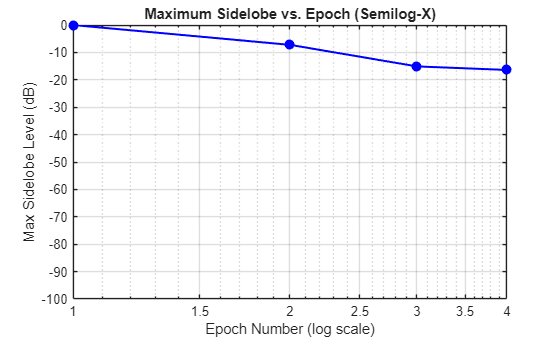

figure;
semilogx(epochs, sl_valid, '-ob', 'LineWidth', 1.5, 'MarkerFaceColor', 'b');
grid on;

xlabel('Epoch Number (log scale)');
ylabel('Max Sidelobe Level (dB)');
title('Maximum Sidelobe vs. Epoch (Semilog-X)');

ylim([-100 0]);
xlim([1 last_valid]);

outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
fname = 'MaxSide_vs_LogEpoch_No_Null.fig';
savefig( fullfile(outdir, fname) );
%savefig(gcf, 'MaxSide_vs_EpochLog_Null_90deg_cont.fig');

## Run a sweep over several Focus Angles for (2-Beam) version of the Method:

% because it seems to glitch without this:
saveDir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Saved_Results';


%% Sweep setup
Max_iter = 100;
eps_dB = -20;
phi_0_1 = deg2rad(0);
%phi_0_2 = deg2rad(120);
focus_split = 125; % the degree split between focus beams for the sweep
focusAngles_deg = 0:1:360;   % Example sweep
%focusAngles_deg = 0:1:10;   % Example sweep
numAngles = numel(focusAngles_deg);
test_As = ones(numel(x),1);
phi = linspace(0, 2*pi, 1000);   % MUST match algorithm
nPhi = numel(phi);

F_final_store = NaN(numAngles, nPhi);   % magnitude
max_SL_all   = cell(numAngles, 1);   % cell array of sidelobe vectors
epochs_all   = zeros(numAngles, 1);  % store final epoch count
Big_phi_final_1 = NaN(numAngles, 1); % store final  
right_bound_1   = NaN(numAngles, 1);  % store right half power beam bound
left_bound_1   = NaN(numAngles, 1);  % store left half power beam bound
main_peak_skew_1 = zeros(numAngles, 1);  %store results for diffrence between main beam and focus angle
Big_phi_final_2 = NaN(numAngles, 1); % store final  
right_bound_2   = NaN(numAngles, 1);  % store right half power beam bound
left_bound_2   = NaN(numAngles, 1);  % store left half power beam bound
main_peak_skew_2 = zeros(numAngles, 1);  %store results for diffrence between main beam and focus angle
phi0_all_rad = deg2rad(focusAngles_deg);
badAngles = false(numAngles,1); % setup for recording bad angles

%% Sweep loop
for i = 1:numAngles
    try
        %phi_0_1 = deg2rad(0);
        phi_0_1 = deg2rad(focusAngles_deg(i));
        phi_0_2 = deg2rad(focusAngles_deg(i)+focus_split);
        
        results = perturb_method_2_beam_v2(x, y, phi_0_1, phi_0_2,...
        'Max_iter', Max_iter, ...
        'eps_dB', eps_dB, ...
        'show_plot_init', false);
        
        %fprintf('Made it to Sweep iter %d.\n', i);
        fprintf('Sweep iter %d OK (%.1f deg)\n', i, focusAngles_deg(i));

        bw1 = directivity_met_v2(phi, results.final_function, phi_0_1);
        bw2 = directivity_met_v2(phi, results.final_function, phi_0_2);        
        
        % Store relevant data
        % ---- Store results normally ----
        max_SL_all{i} = results.max_sidelobe_store;
        epochs_all(i) = results.final_epoch;
        F_at_focus_1(i) = results.F_at_phi_0_1;
        F_at_focus_2(i) = results.F_at_phi_0_2;
        F_final_store(i, :) = results.final_function;
        Big_phi_final_1(i) = results.Big_phi_final_1;
        Big_phi_final_2(i) = results.Big_phi_final_2;
        right_bound_1(i) = bw1.right_05;
        right_bound_2(i) = bw2.right_05;
        left_bound_1(i) = bw1.left_05;
        left_bound_2(i) = bw2.left_05;
        main_peak_skew_1(i) = results.main_peak_skew_1(results.final_epoch);
        main_peak_skew_2(i) = results.main_peak_skew_2(results.final_epoch);

    catch ME
        % ---- Mark as bad ----
        badAngles(i) = true;

        fprintf('*** Sweep iter %d FAILED at %.1f deg ***\n', ...
                 i, focusAngles_deg(i));
        fprintf('%s\n', ME.message);

        % ---- Fill safe defaults ----
        max_SL_all{i}       = NaN;
        epochs_all(i)       = NaN;
        F_at_focus_1(i)     = NaN;
        F_at_focus_2(i)     = NaN;
        F_final_store(i,:)  = NaN;
        Big_phi_final_1(i)  = NaN;
        Big_phi_final_2(i)  = NaN;
        right_bound_1(i)    = NaN;
        right_bound_2(i)    = NaN;
        left_bound_1(i)     = NaN;
        left_bound_2(i)     = NaN;
        main_peak_skew_1(i) = NaN;
        main_peak_skew_2(i) = NaN;

        continue;        
    end
end

Sweep iter 1 OK (0.0 deg)
Sweep iter 2 OK (1.0 deg)
Sweep iter 3 OK (2.0 deg)
Sweep iter 4 OK (3.0 deg)
Sweep iter 5 OK (4.0 deg)
Sweep iter 6 OK (5.0 deg)
Sweep iter 7 OK (6.0 deg)
Sweep iter 8 OK (7.0 deg)
Sweep iter 9 OK (8.0 deg)
Sweep iter 10 OK (9.0 deg)
Sweep iter 11 OK (10.0 deg)
Sweep iter 12 OK (11.0 deg)
Sweep iter 13 OK (12.0 deg)
Sweep iter 14 OK (13.0 deg)
Sweep iter 15 OK (14.0 deg)
Sweep iter 16 OK (15.0 deg)
Sweep iter 17 OK (16.0 deg)
Sweep iter 18 OK (17.0 deg)
Sweep iter 19 OK (18.0 deg)
Sweep iter 20 OK (19.0 deg)
Sweep iter 21 OK (20.0 deg)
Sweep iter 22 OK (21.0 deg)
Sweep iter 23 OK (22.0 deg)
Sweep iter 24 OK (23.0 deg)
Sweep iter 25 OK (24.0 deg)
Sweep iter 26 OK (25.0 deg)
Sweep iter 27 OK (26.0 deg)
Sweep iter 28 OK (27.0 deg)
Sweep iter 29 OK (28.0 deg)
Sweep iter 30 OK (29.0 deg)
Sweep iter 31 OK (30.0 deg)
Sweep iter 32 OK (31.0 deg)
Sweep iter 33 OK (32.0 deg)
Sweep iter 34 OK (33.0 deg)
Sweep iter 35 OK (34.0 deg)
Sweep iter 36 OK (35.0 deg)
Sweep iter 


%% Convert cell array → padded matrix

%% Trim each sidelobe vector to its actual recorded length
for i = 1:numAngles
    v = max_SL_all{i};

    % Valid sidelobes are real numbers between 0 and -200 dB
    validIdx = find(v <= 0 & v >= -200);

    if isempty(validIdx)
        max_SL_all{i} = -40;      % fallback
    else
        lastGood = validIdx(end);
        max_SL_all{i} = v(1:lastGood);
    end
end

%% Diagnostic: check sidelobe vector lengths for each angle
%{
fprintf("\n=== Sidelobe vector lengths per angle ===\n");
for i = 1:numAngles
    L = length(max_SL_all{i});
    fprintf("Angle %4.0f deg → length = %d\n", focusAngles_deg(i), length(max_SL_all{i}));
end
%}

% Find longest run (max epoch count)
maxLen = max( cellfun(@length, max_SL_all) );
%fprintf("\nMax sidelobe-store length = %d\n", maxLen);

% Preallocate with NaNs (which surf will skip)
SL_matrix = NaN(numAngles, maxLen);

for i = 1:numAngles
    L = length(max_SL_all{i});
    SL_matrix(i, 1:L) = max_SL_all{i};
end

%% === Extract final-epoch sidelobe for each angle ===
SL_final = zeros(numAngles,1);

for i = 1:numAngles
    v = max_SL_all{i};
    if isempty(v)
        SL_final(i) = NaN;    % should not happen, but safe
    else
        SL_final(i) = v(end); % final epoch sidelobe
    end
end

%% ---- Save sweep data ----
saveFile = fullfile(saveDir, 'sidelobe_sweep_2beam.mat');

save(saveFile, ...
    'SL_matrix', ...
    'max_SL_all', ...
    'SL_final', ...
    'focusAngles_deg', ...
    'epochs_all', ...
    'F_final_store', ...
    'phi', ...
    'badAngles', ...
    'maxLen', ...
    'eps_dB', ...
    'Max_iter');



## Compare Double-Cross vs. Regular N-gon Geometry

%% Shared Base Variables
Max_iter = 200; %The algithm goes to step maxiter
eps_dB = -20;
phi_0_1 = deg2rad(0);
phi_0_2 = deg2rad(210);
phi_0_set = [phi_0_1 phi_0_2];
%phi_0 = deg2rad(0);
%null_phi_list = deg2rad([120]);
null_phi_list_1 = phi_0_2;
null_phi_list_2 = phi_0_1;
cone_rad = deg2rad(30);
N = 9;
%N = numel(x);
phi = linspace(0, 2*pi, 1000+1);   % MUST match algorithm
phi(end) = [];   % remove 2π duplicate
nPhi = numel(phi);

%% Double Cross Version
% Initialize Eric's 'better' 9-element version (specifically for 120 degrees)
d1 = 0.049553426571036;
d2 = 0.049015017974167;
[x,y] = d1d2Convert(d1,d2,N);

results_1 = perturb_method_2_beam_v3(x, y, phi_0_1, phi_0_2, ...
    'Max_iter', Max_iter, ...
    'eps_dB', eps_dB, ...
    'null_phi', null_phi_list_1, ...
    'show_plot_raw', false, ...
    'show_plot_init', false, ...
    'show_plots_st7', false, ...
    'show_plots_st12', false, ...
    'show_final_plot',  true, ...
    'cone_rad', cone_rad);

%% Regular N-gon Version
% Initialize "All on one ring" version of the 9-element "double cross" coordinates
% This is equivalent to an regular octogon with radius 0.05 starting at (0.05,0).
%z = zeros(1,N);
d1 = 0.04880;
d2 = 0.04880;
[x,y] = d1d2Convert(d1,d2,9); %Change to 5,9,13 apropriatly


results_2 = perturb_method_2_beam_v3(x, y, phi_0_1, phi_0_2, ...
    'Max_iter', Max_iter, ...
    'eps_dB', eps_dB, ...
    'null_phi', null_phi_list_1, ...
    'show_plot_raw', false, ...
    'show_plot_init', false, ...
    'show_plots_st7', false, ...
    'show_plots_st12', false, ...
    'show_final_plot',  true, ...
    'cone_rad', cone_rad);

%% Combine run data
runs = {results_1, results_2};
labels = {"Double Cross", "Regular N-gon"};
Nruns = numel(runs);

%% Extract and Trim Data from Each Run
sl_all = cell(Nruns,1);
bw_all = cell(Nruns,1);
epochs_all = cell(Nruns,1);
F_focus_all = cell(Nruns,1);
G_all = cell(Nruns,1);

for r = 1:Nruns

    res = runs{r}; % set target results

    sl_store = res.max_sidelobe_store;
    bw_store = res.directivity_metric_1_beamwidth_store;
    F_focus_store = res.focus_value_store;
    %G = function gain_calc(F_total, phi_mesh, phi0)
    G_store = gain_calc(res.F_store, phi, phi_0);

    % Determine valid entries
    valid_mask = ~(isnan(sl_store) | isinf(sl_store));
    last_valid = find(valid_mask, 1, 'last');

    if isempty(last_valid)
        error('Run %d has no valid sidelobe entries.', r);
    end

    % Trim
    sl_all{r} = sl_store(1:last_valid);
    bw_all{r} = bw_store(1:last_valid);
    F_focus_all{r} = F_focus_store(1:last_valid);
    epochs_all{r} = 1:last_valid;
    G_all{r} = G_store(1:last_valid);

end

## CPU Time Test (superposition)

%N = 1e5;                    % adjust until total time is > 1 second
N = 1e2;                    % adjust until total time is > 1 second
t0 = cputime;
for k = 1:N
    %myFunction(x, y);
    Max_iter = 200; %The algithm goes to step maxiter
    eps_dB = -20;
    %phi_0 = deg2rad(0);
    %null_phi_list = deg2rad([]);
    phi_0_1 = deg2rad(225);
    phi_0_2 = deg2rad(225+120);
    %phi_0_set = [phi_0_1 phi_0_2];
    %null_phi_list_1 = phi_0_2;
    %null_phi_list_2 = phi_0_1;
    %cone_rad = deg2rad(30);
    %cone_rad = [];
    
    results_2b = perturb_method_2_beam_v6(x, y, phi_0_1, phi_0_2,...
    'Max_iter', Max_iter, ...
    'eps_dB', eps_dB, ...
    'show_plot_init', false, ...
    'cone_rad', []);

end
cpu_per_call_ms = (cputime - t0) / N * 1000;
fprintf('CPU time per call: %.4f ms\n', cpu_per_call_ms);

CPU time per call: 22.8125 ms


%% Sweep: 2-Beam Advanced method at 4 primary focus directions — gains, skews, max sidelobe


phi_deg_list_1   = [0 45 135 225];
secondary_offset = 120;            % phi_0_2 = phi_0_1 + 120° CCW
Max_iter         = 200;
eps_dB           = -20;
cone_rad         = deg2rad(15);    % constraint cone radius around each focus
d1 = 0.04880;
d2 = 0.04880;
N  = 9;
[x, y] = d1d2Convert(d1, d2, N);

fprintf('\n');
fprintf('  phi_1   phi_2    G2D_1        G2D_2        G3D_1        G3D_2       skew_1    skew_2     BW_1      BW_2    max sidelobe\n');

  phi_1   phi_2    G2D_1        G2D_2        G3D_1        G3D_2       skew_1    skew_2    max sidelobe


fprintf('  -----   -----    -----        -----        -----        -----       ------    ------     ----      ----    ------------\n');

  -----   -----    -----        -----        -----        -----       ------    ------    ------------



for k = 1:numel(phi_deg_list_1)
    phi_0_1_deg = phi_deg_list_1(k);
    phi_0_2_deg = mod(phi_0_1_deg + secondary_offset, 360);
    phi_0_1 = deg2rad(phi_0_1_deg);
    phi_0_2 = deg2rad(phi_0_2_deg);

    r = perturb_method_2_beam_v6(x, y, phi_0_1, phi_0_2, ...
        'Max_iter',        Max_iter, ...
        'eps_dB',          eps_dB, ...
        'cone_rad',        cone_rad, ...
        'final_metrics',   true, ...
        'show_plots',      false, ...
        'show_final_plot', false, ...
        'verbose',         false);

    fprintf(['  %3d°    %3d°   %9.3f dB %9.3f dB %9.3f dB %9.3f dB' ...
             '   %7.3f°  %7.3f°  %7.3f°  %7.3f°    %9.3f dB\n'], ...
        phi_0_1_deg, ...
        phi_0_2_deg, ...
        r.final_gain2D_1, ...
        r.final_gain2D_2, ...
        r.final_gain3D_1, ...
        r.final_gain3D_2, ...
        r.main_beam_skew_final_1_deg, ...
        r.main_beam_skew_final_2_deg, ...
        r.beamwidth_1_deg, ...

Unrecognized field name "final_gain2D_1".

        r.beamwidth_2_deg, ...
        r.final_max_sidelobe_dB);
end
fprintf('\n');